 
clear
[scenario, testName] = oblongTest;
video1 = false;
video2 = true;

bounds = roadBoundaries(scenario);

outerBounds = flip(bounds{1}(:,1:2),1);
innerBounds = bounds{2}(:,1:2);
centers = horzcat(mean([innerBounds(:,1), outerBounds(:,1)],2),mean([innerBounds(:,2), outerBounds(:,2)],2));

centersDiff = [0; sqrt(sum((centers(2:end,:)-centers(1:end-1,:)).^2,2))];
sVals = cumsum(centersDiff);

normFactor = floor(sVals(end))/sVals(end);

centersNormalized = centers.*normFactor;
sValsNormalized = sVals.*normFactor;

waypoints = [spline(sValsNormalized, centersNormalized(:,1),0:sValsNormalized(end))',...
             spline(sValsNormalized, centersNormalized(:,2),0:sValsNormalized(end))'];

tic
[waypointsFit, videoSet, videoSetPt] = discreteWaypointOptimizer(waypoints, normFactor*3, 50, 0.05, 0.1, testName);

Iteration: 1.000000/nOptimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: me

t = toc;
fprintf('Optimization Complete . . . Beginning Video Output: %f',t);

Optimization Complete . . . Beginning Video Output: 78.432662

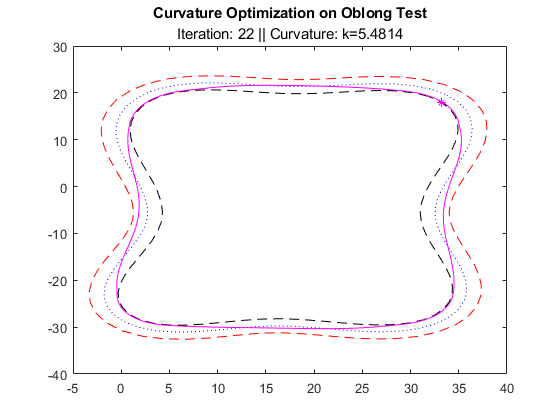

Video 2 Complete: 608.900746


videoSet(:,1) = cellfun(@(x) x/normFactor, videoSet(:,1), 'un',0);
videoSetPt(:,1) = cellfun(@(x) x/normFactor, videoSetPt(:,1), 'un',0);

videoSet(:,3) = cellfun(@(x) x/normFactor, videoSet(:,3), 'un',0);
videoSetPt(:,3) = cellfun(@(x) x/normFactor, videoSetPt(:,3), 'un',0);

waypointsFit = waypointsFit./normFactor;

if video1
    tic
    writer1(videoSet, testName, centers, innerBounds, outerBounds);
    t=toc;
    fprintf('Video 1 Complete . . . Beginning Video 2: %f',t);
end

if video2
    tic
    writer2(videoSetPt, testName, centers, innerBounds, outerBounds);
    t=toc;
    fprintf('Video 2 Complete: %f',t);
end


if ~video1 && ~video2
    plot(centers(:,1), centers(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), '--k',...
        innerBounds(:,1), innerBounds(:,2), '--r',...
        waypointsFit(:,1), waypointsFit(:,2), 'm',...
        'Visible',"on");
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{end,2}),' || Curvature: k=',num2str(videoSet{end,3})]);
end

function writer1(videoSet, testName, centers, innerBounds, outerBounds)
writer = VideoWriter(testName(testName ~= ' '));
writer.FrameRate = 1;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), '--k',...
        innerBounds(:,1), innerBounds(:,2), '--r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' || Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer2(videoSet, testName, centers, innerBounds, outerBounds)
writer = VideoWriter([testName(testName ~= ' '),'ByPt']);
writer.FrameRate = 60;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), '--k',...
        innerBounds(:,1), innerBounds(:,2), '--r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    plot(videoSet{idxVidSet,4}(1), videoSet{idxVidSet,4}(2),'*m');
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' || Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);

end
% [ai] a(v=0) = 0
% [av] a(v=20) = 3
% [am] a(v=40) = 6
% da/dv = ra((am-a)/am)
% da/dt max = 2
% dv/dt max = 5
% dp/dt max = 40
% a = am/(1+be^(-kv))
% 